# Laboratory 2: Di Via & Hiller-Szala

## Introduction  

In this project, we aim to predict the occurrence of solar flares within the next 24 hours using data from HARPs recorded by NASA's Helioseismic and Magnetic Imager (HMI), which is an instrument part of Solar Dynamics Observatory (SDO), a mission launched in 2010 to understand the causes of the sun's activities and their impacts on the Earth. The HMI provides valuable data on solar activity, such as sunspots and magnetic field patterns, allowing researchers to study solar dynamics and predict space weather phenomena.

The Sun is a dynamic star whose activity follows a roughly 10–11 year solar cycle, characterized by periodic variations in the number of sunspots, solar flares, and coronal mass ejections. Solar flare is a sudden increase in electromagnetic radiation, typically in the range of UV to soft X-rays, from the solar atmosphere (mostly the chromosphere and corona). This radiation is primarily thermal in nature, coming from regions of localized heating caused by magnetic energy release called **active regions (ARs)**. The flare importance is defined by its relative brightness and total area. The classification system is the following:

- **A-class**: The weakest flares;

- **B-class**: Minor flares with negligible effects on Earth;

- **C-class**: Small flares with limited impact;

- **M-class**: Medium-sized flares that can cause brief radio blackouts;

- **X-class**: The largest and most impactful flares, capable of triggering widespread radio blackouts and long-lasting radiation storms.

Not every AR give rise to flares. For automated monitoring of solar active regions (ARs), each active region AR on the Sun is assigned a **HARPs (HMI Active Region Patches)** number by the HMI, allowing its life cycle to be tracked through magnetograms captured every 12 minutes. From HMI images, it's possible to extract up to 200 features per AR, focusing on magnetic field properties and morphological complexity, which are useful to solar flares prediction, crucial for understanding the underlying physical mechanisms and for mitigating their operational impacts, including risks to spacecrafts, communication disruptions and blackouts.

The following image, taken from the paper "[An Introduction on Solar Imaging Data Analytic Challenges and Opportunities for Statisticians](https://www.researchgate.net/publication/380757410_An_Introduction_on_Solar_Imaging_Data_Analytic_Challenges_and_Opportunities_for_Statisticians?_tp=eyJjb250ZXh0Ijp7ImZpcnN0UGFnZSI6Il9kaXJlY3QiLCJwYWdlIjoicHVibGljYXRpb24ifX0)" (by the authors [Yang Chen](https://www.researchgate.net/profile/Yang-Chen-202?_sg%5B0%5D=m2qNoSM9TQWrQcq5MFK84FzJa1NUVkuz4XwjdS7Fss6_Z0GfdRWw9ou6VKdMwOQjs4DA-0s.34-_Hf5-0E7u2s0ZW6JX6wdMish9-cpKDi72ALBVcRe2muXEQggxnjFO98o-aBdhclxE0aFTJMU4Jh932f3nBw&_sg%5B1%5D=C2BNiwt9BPc-8-kzsn_xn33J0gjp-9vEcDU5AuQsQQL0k992EsCSwsYLDnBM7HmAx8Nnrek.r-m4beDoShQbBF9ySH_1B3lAfNyjVj2c6a4L5Z8zjj7Hq978wBZ8ubdyLF7oIJ0xckxSF3t5Z60iz4STko20Cg&_tp=eyJjb250ZXh0Ijp7ImZpcnN0UGFnZSI6Il9kaXJlY3QiLCJwYWdlIjoicHVibGljYXRpb24iLCJwcmV2aW91c1BhZ2UiOiJwdWJsaWNhdGlvbiIsInBvc2l0aW9uIjoicGFnZUhlYWRlciJ9fQ), [Ward Manchester](https://www.researchgate.net/scientific-contributions/Ward-Manchester-2276423953?_sg%5B0%5D=m2qNoSM9TQWrQcq5MFK84FzJa1NUVkuz4XwjdS7Fss6_Z0GfdRWw9ou6VKdMwOQjs4DA-0s.34-_Hf5-0E7u2s0ZW6JX6wdMish9-cpKDi72ALBVcRe2muXEQggxnjFO98o-aBdhclxE0aFTJMU4Jh932f3nBw&_sg%5B1%5D=C2BNiwt9BPc-8-kzsn_xn33J0gjp-9vEcDU5AuQsQQL0k992EsCSwsYLDnBM7HmAx8Nnrek.r-m4beDoShQbBF9ySH_1B3lAfNyjVj2c6a4L5Z8zjj7Hq978wBZ8ubdyLF7oIJ0xckxSF3t5Z60iz4STko20Cg&_tp=eyJjb250ZXh0Ijp7ImZpcnN0UGFnZSI6Il9kaXJlY3QiLCJwYWdlIjoicHVibGljYXRpb24iLCJwcmV2aW91c1BhZ2UiOiJwdWJsaWNhdGlvbiIsInBvc2l0aW9uIjoicGFnZUhlYWRlciJ9fQ), [Meng Jin](https://www.researchgate.net/profile/Meng-Jin-11?_sg%5B0%5D=m2qNoSM9TQWrQcq5MFK84FzJa1NUVkuz4XwjdS7Fss6_Z0GfdRWw9ou6VKdMwOQjs4DA-0s.34-_Hf5-0E7u2s0ZW6JX6wdMish9-cpKDi72ALBVcRe2muXEQggxnjFO98o-aBdhclxE0aFTJMU4Jh932f3nBw&_sg%5B1%5D=C2BNiwt9BPc-8-kzsn_xn33J0gjp-9vEcDU5AuQsQQL0k992EsCSwsYLDnBM7HmAx8Nnrek.r-m4beDoShQbBF9ySH_1B3lAfNyjVj2c6a4L5Z8zjj7Hq978wBZ8ubdyLF7oIJ0xckxSF3t5Z60iz4STko20Cg&_tp=eyJjb250ZXh0Ijp7ImZpcnN0UGFnZSI6Il9kaXJlY3QiLCJwYWdlIjoicHVibGljYXRpb24iLCJwcmV2aW91c1BhZ2UiOiJwdWJsaWNhdGlvbiIsInBvc2l0aW9uIjoicGFnZUhlYWRlciJ9fQ), [Alexei Pevtsov](https://www.researchgate.net/scientific-contributions/Alexei-A-Pevtsov-10330861?_sg%5B0%5D=m2qNoSM9TQWrQcq5MFK84FzJa1NUVkuz4XwjdS7Fss6_Z0GfdRWw9ou6VKdMwOQjs4DA-0s.34-_Hf5-0E7u2s0ZW6JX6wdMish9-cpKDi72ALBVcRe2muXEQggxnjFO98o-aBdhclxE0aFTJMU4Jh932f3nBw&_sg%5B1%5D=C2BNiwt9BPc-8-kzsn_xn33J0gjp-9vEcDU5AuQsQQL0k992EsCSwsYLDnBM7HmAx8Nnrek.r-m4beDoShQbBF9ySH_1B3lAfNyjVj2c6a4L5Z8zjj7Hq978wBZ8ubdyLF7oIJ0xckxSF3t5Z60iz4STko20Cg&_tp=eyJjb250ZXh0Ijp7ImZpcnN0UGFnZSI6Il9kaXJlY3QiLCJwYWdlIjoicHVibGljYXRpb24iLCJwcmV2aW91c1BhZ2UiOiJwdWJsaWNhdGlvbiIsInBvc2l0aW9uIjoicGFnZUhlYWRlciJ9fQ)) illustrates data used for solar flare prediction. Although it is not directly associated with our laboratory, we considered it a useful example.

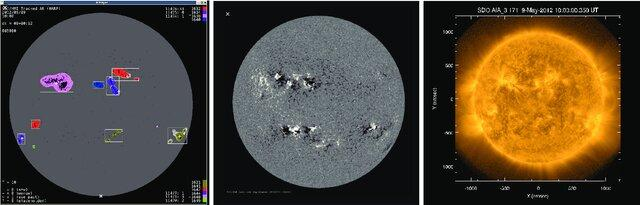

- The left panel shows an example of HARPs, highlighted in colored contours enclosed in boxes. 

- The middle panel shows and example of HMI magnetogram data, in gray-scale, where intense active regions are shown as opposite magnetic polarities appearing in black and white. White regions are associated to the presence of a magnetic field, while black regions negative. 

- The right panel shows an example of AIA extreme ultraviolet image, taken in the 171 Angstrom band.

By analyzing the properties of HARPs, scientists can assess the likelihood of flare events. Various tasks can be performed using this data, but our focus will be on binary classification determining whether a flare event occurs or not.

## Mathematical Background

To evaluate the likelihood of flare events, it is essential to understand theoretical concepts related to learning and optimization problems.

### Learning Problem

Let $(X, Y): \Omega \to X \times Y$ be a random variable with joint distribution $\rho$. We consider supervised learning problems where each data point has a known label. Given $n$ samples, the **training set** is defined as $T_n = \{(x_i, y_i) \in X \times Y \mid i = 1, \ldots, n\}$, where $X \subseteq \mathbb{R}^p$ is the input space and $Y \subseteq \mathbb{R}$ is the output space. Assuming that $Y$ is a Polish space and $(x_i, y_i)_{i=1,...,n}$ are independent and identically distributed (i.i.d.) copies of $(X, Y)$ under $\rho$, we decompose $\rho(x, y)$ as $\rho(y \mid x)\nu(x)$, where $\rho(y \mid x)$ is the conditional distribution of $Y$ given $X$ and $\nu(x)$ is the marginal distribution of $X$. 

The goal is to find a measurable **target function** $f: X \to \mathbb{R}$ such that $f(x_i) \approx y_i$ for $i = 1, \ldots, n$ and generalizes well to unseen inputs. We define the** loss function** $L: Y \times Y \to [0, \infty)$ measurable, to estimate the prediction error. Using the quadratic loss $L(y, f(x)) = (y - f(x))^2$, the target function minimizing the expected risk $R(f) = \int_{X \times Y} L(y, f(x))d\rho(x, y)$ is $f^*(x) = \int_Y y d\rho(y \mid x)$. Since $\rho$ is only known on the training set, the empirical risk with quadratic loss is defined as $R_{T_n}(f) = \frac{1}{n}\sum_{i=1}^n (y_i - f(x_i))^2$.

Thus, the learning problem reduces to minimizing the empirical risk: $\hat{f} \in  \arg\min_{f \in H} R_{T_n}(f)$, where $H$ is the space of measurable functions. For simplicity, we assume a linear model $f(x) = \langle x, \beta \rangle = x^T \beta$, where $X$ is an $n \times p$ data matrix, and $y$ is an $n \times 1$ label vector. The problem becomes: 

$\hat{\beta} \in  \arg\min_{\beta \in \mathbb{R}^p} \frac{1}{n} \sum_{i=1}^n (y_i-<x,\beta>)^2= \arg\min_{\beta \in \mathbb{R}^p} \frac{1}{n}||y - X\beta||_2^2$. 

The quadratic loss is convex, so $\nabla L(\beta) = 0$ yields to the solution $\beta = (X^T X)^{-1} X^T y$ (if $n \geq p$) and $\beta = X^T (X X^T)^{-1} y$ (if $n<p$). However, decomponing $X=U\Sigma V^T$ via singular value decomposition (SVD), where $\Sigma=diag(\sigma_1,...,\sigma_r)$, we obtain $\beta=\sum_{i=1}^r \frac{1}{\sigma_j}<u_j, y>v_j$ meaning that small singular values in $X$ amplify errors, necessitating regularization. Using Tikhonov regularization, with penalty $\lambda ||\beta||_2^2$, the modified problem is: 

$\nabla L(\beta) = \frac{2}{n}X^T (X\beta - y) + \frac{2}{n}\lambda \beta = 0 \Longleftrightarrow (X^T X + \lambda I)\beta = X^T y \Longleftrightarrow \beta=(X^TX+\lambda I)^{-1}X^Ty$. 

Decomponing via SVD, this becomes $\beta = \sum_{i=1}^r \frac{\sigma_i}{\sigma_i^2 + \lambda}\langle u_i, y\rangle v_i$, offering a stable solution. This study employs **LASSO (Least Absolute Shrinkage Operator)** regularization instead, adding an $l_1$-penalty term: 

$\hat{\beta}_{LASSO} = \arg\min_{\beta \in \mathbb{R}^p} \frac{1}{2}||y - X\beta||_2^2 + \lambda||\beta||_1$. 

The $l_1$ penalty induces sparsity, retaining only significant features, as the active set $\mathcal{A}=\{ j=1,...,p| \beta_j \neq 0 \}$ is such that $\# \mathcal{A} << p$ . This is advantageous as it approximates the zero norm, but is convex, leading to efficient computation.

### Proximal Gradient Algorithm to solve the Learning Problem

Given $H$ an Hilbert space, the problem can be summarized as the following: $\arg \min_{u \in H} F(u)+R(u)$, where 

- $F(\cdot)=|| \cdot ||_2^2$ is strongly convex, differentiable and its gradient is $L$-Lipschitz, with $L=||X^TX||_2$ in our case;

- $R(\cdot)= ||\cdot||_1$is proper convex, semi-lower continous and it's not differentiable.

Due to the not differentiability of $R$, we define the notion of subgradient. Given $u \in H$ and $h:H \longrightarrow \mathbb{R}$ a convex function, the **subdifferential** of $h$ at $u$ is defined as

$\partial h(u)=\{ w \in H | h(z) \geq h(u)+\langle w, z-u \rangle_H \quad \forall z \in H \}$, 

and its elements are called **subgradients**. Some key properties are listed below:

- $u^*$ is a global minimum of $h$ $\Longleftrightarrow$ $0 \in \partial h(u^*)$; 

- $h$ is differentiable in $u$ $\Longrightarrow$ $\partial h(u)=\{\nabla h(u)\}$; 

- $g,h$ proper, semi-lower continous, convex functions and $\text{dom}^o g \cap \text{dom } h \neq \emptyset$  $\Longrightarrow$ $\partial g(u) + \partial h(u) = \partial (g+h)(u)$ $\forall u \in H$. 

Given $u \in H$ and $h:H \longrightarrow \mathbb{R}$ a proper convex, semi-lower continous function and $\alpha>0$, the** proximal operator** is defined as follows: 

$\text{prox}_{\gamma h}: H \longrightarrow H$ such that $\text{prox}_{\gamma h}(u)=\arg \min_{z \in H}\{h(z)+\frac{1}{2}||u-z||^2\}$.

 It can be characterized as: $p=\text{prox}_{\gamma h}(u) \Longleftrightarrow \frac{u-p}{\gamma} \in \partial h(p) \Longleftrightarrow p=(I+\gamma \partial h)^{-1}(u)$. This characterization allows us to solve the problem using the** proximal gradient algorithm**:


$$u^* \in \arg \min_{u \in H} F(u)+R(u) \Longleftrightarrow 0 \in \partial (F+R)(u^*) \Longleftrightarrow 0 \in \nabla F(u^*)+ \partial R(u^*) \Longleftrightarrow - \nabla F(u^*) \in \partial R(u^*) \Longleftrightarrow$$
 

$\Longleftrightarrow u^* - \gamma \nabla F(u^*) \in  u^*+\gamma \partial R(u^*) \Longleftrightarrow  u^* - \gamma \nabla F(u^*) \in (I+\gamma \partial R)(u^*) \Longleftrightarrow u^*=\text{prox}_{\gamma R} (u^*-\gamma \nabla F(u^*))$.

### Averaged Operators and Convergence 

Given $\alpha \in (0,1)$ we say an operator $T:X \longrightarrow X$ is $\alpha$**-averaged **if $\exists R: X \longrightarrow X$ operator such that $||Rx-Ry||\leq ||x-y|| \forall x,y, \in X$ and $T=(1-\alpha)I+\alpha R$.

It's possible to prove that, for an $\alpha$-averaged operator $T$ with a non-empty set of fixed points, the iterative sequence defined by$x_0 \in X$ and $x_{k+1}=Tx_k$ converges to a fixed point of $T$.

Since the proximal operator is an $\frac{1}{2}$-averaged operator, the proximal gradient algorithm converges if $\gamma \in (0, \frac{2}{L})$, with $L$ the Lipschitz constant of $\nabla F$, and its **convergence rate** is $O(\frac{1}{k})$.

### ISTA and FISTA Algorithms

In the context of LASSO, the **Iterative Shrinkage Thresholding Algorithm (ISTA)** addresses the following iterative problem:

$\hat{\beta}_{\text{LASSO}}^{(k+1)}=\text{prox}_{\gamma \lambda || \cdot ||_1}(\beta^{(k)}-\gamma \nabla(\frac{1}{2}||y - X\beta^{(k)}||_2^2))=\text{prox}_{\gamma \lambda || \cdot ||_1}(\beta^{(k)}-\gamma X^T(y - X\beta^{(k)}))$.

The regularization term can be expressed as $R(u)=\lambda ||u||_1= \lambda\sum_{j=1}^p |u_j|= \lambda \sum_{j=1}^p R_j(u_j)$, where $R_j: \mathbb{R} \longrightarrow \mathbb{R}$ is defined as $R_j(u)=|u| \quad \forall u \in H$. 

Thus, the proximal operator $\text{prox}_{\gamma R}: \mathbb{R}^p \longrightarrow \mathbb{R}^p$ can be written as the vector $(\text{prox}_{\gamma R_1} (u_1), \cdots, \text{prox}_{\gamma R_p}(u_p))$. 

Using the characterization of the proximal operator and the subgradient of the absolute value $\partial |\cdot | (u_j^*)= \begin{cases} 1 \quad \text{if } u_j^* >0 \\ [-1,1] \quad \text{if } u_j^*=0 \\ -1 \quad \text{if } u_j^*<0 \end{cases},$ it follows that the $\text{prox}_{\gamma R}(u)=(S_{\gamma \lambda}(u_1), \cdots, S_{\gamma \lambda }(u_p))$ where $S_{\gamma \lambda}$ is called **Soft Thresholding Operator**, and it's defined as $S_{\gamma \lambda}(u_j)= \text{prox}_{\gamma \lambda |\cdot|}(u_j)= \begin{cases} u_j - \gamma \lambda \quad \text{if } u_j>\gamma \lambda \\
0 \quad \text{if } |u_j|\leq \gamma \lambda \\
u_j+\gamma \lambda \quad \text{if } u_j < -\gamma \lambda \end{cases}= \text{sign }(u_j) \max(|u_j|-\gamma \lambda, 0)$.

 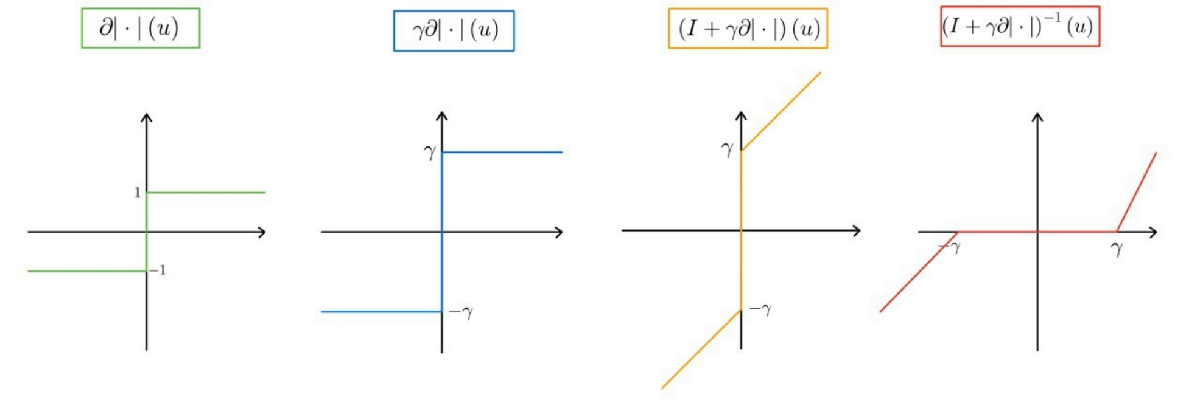

The method can be accelerated to achieve a convergence rate of $O(\frac{1}{k^2})$ by incorporating momentum terms that contain information from the previous iterations. Given $k \geq 0$, $\alpha^{(0)}=\beta^{(0)}=0_p$ and $t^{(0)}=1$ the **Fast Iterative Shrinkage Algorithm (FISTA)** is defined as

$\begin{cases} \beta^{(k+1)}=S_{\gamma \lambda}(\alpha^{(k)}+ \gamma X^T(y-X\alpha^{(k)})) \\
\alpha^{(k+1)}=\beta^{(k+1)}+\frac{t^{(k)}-1}{t^{(k+1)}}(\beta^{(k+1)}-\beta^{(k)})\\
t^{(k+1)}=1+\frac{\sqrt{1+4 (t^{(k)})^2}}{2}
 \end{cases}$.

## Solar Flares Prediction

After computing the optimal $\hat{\beta}_{\text{LASSO}}$ that minimizes the classification problem, we estimate the quality of the predictions. First, we calculate the predictions on the training set: $\hat{p}=X\hat{\beta}_{\text{LASSO}}$. The binary classification output is obtained by defining:  $\hat{y}=\begin{cases} 1 \quad \text{if } \hat{p}\geq \tau \\ 0 \quad \text{if }\hat{p}<\tau \end{cases}$. 

To choose the **optimal threshold **$\tau_{opt}$ we define a range of 100 thresholds to consider, by defining the grid: 

$a=\min(\hat{p})$, $b=\max(\hat{p})$, $\tau_j=a+j\delta$ where $\delta=\frac{b-a}{N}$, $N=100$ and $j=0,\cdots, N-1$.

Then we choose the threshold that maximize the **True Skill Statistic (TSS)**, as follows: 

$\tau_{opt}= \arg \max_{(\tau_j)_{j=1}^{N-1}} \text{TSS}(y, \hat{y}(\tau_j))$.

TSS is particularly useful metric for unbalanced datasets, where the number of positive samples is much smaller than the number of negative ones. It is defined as

$TSS=\frac{TP}{TP+FN}+\frac{TN}{TN+FP}-1 \in [-1,1]$,

 where 

- $TP=\sum_{i=1}^n y_i \hat{y}_i$ denotes the number of positive samples predicted as positive

- $TN=\sum_{i=1}^n (1-y_i)(1-\hat{y}_i)$ denotes the number of negative samples predicted as negative

- $FN=\sum_{i=1}^n (1-\hat{y}_i)y_i$ denotes the number of positive samples predicted as negative

- $FP=\sum_{i=1}^n (1-y_i)\hat{y}_i$ denotes the number of negative samples predicted as positive

Another common metric used is **Accuracy** defined as $ACC=\frac{TP+TN}{TP+TN+FP+FN} \in [0,1]$ and it measures the proportion of correct predictions among the total number of samples.

Once the optimal $\tau$ is determined, predictions can be tested on the test set:

$\hat{p}_{\text{test}}=X_{\text{test}} \cdot \hat{\beta}_{\text{LASSO}}$,  $y_{\text{test}}=\begin{cases} 1 \quad \text{if } \hat{p}_{\text{test}}\geq \tau_{opt}\\ 0 \quad \text{if }\hat{p}_{\text{test}}<\tau_{opt} \end{cases}$.

## Laboratory Introduction

The goal of this laboratory is to predict the occurrence of solar flares using a method based on the FISTA for solving a minimization problem with $l_1$-regularization (LASSO).

The data comes from observations captured by NASA's HMI between September 15, 2012, and April 11, 2013. These observations include 23 features extracted from images of 100 active regions. The model is trained on this historical data and tested on a single observation recorded on April 13, 2013, to validate its performance. 

This approach enables us to assess the potential of machine learning techniques for forecasting solar flares events.

clear all; close all; clc;

## Step 0: Importing Data 

In supervised learning, the dataset consists of X_training and Y_training, where X_training is a matrix containing the input patterns, and Y_training is the corresponding label vector.

- X_training is a matrix $100 \times 23$ containing $P=100$ patterns, characterized by 23 features extracted from images of active regions (ARs). These features capture the physical properties of the ARs that may influence solar flare activity.

- Y_training is a binary vector $100 \times 1$ containing the target labels for each input pattern in X_training. A value of 0 means that the corresponding AR did not produce a flare and there are 85 observations while a value of 1 means that the AR produced at least one flare and there are 15. 

- X_test is a vector $1 \times 23$ containing a single input pattern with the same 23 features as the training set. This pattern corresponds to a solar flare event recorded on April 13, 2013, and it is used to evaluate the performance and predictive accuracy of the trained model.

% Loading data, split into Training and Test sets
X_training=importdata("X_training_standardizzato.mat");
Y_training=importdata("Y_training.mat");
X_test=importdata("X_test_standardizzato.mat");

## Step I: FISTA Implementation for LASSO problems

We define the gradient of the least squares cost function and the soft-thresholding proximity operator, as described in the **Mathematical Background** section. Utilizing these, we call the FISTA function to iteratively solve the LASSO problem. Additionally, we define a model function to represent the problem being solved, enabling us to keep track of the iteration values effectively.

Convergence reached in 2553 iterations.
Beta vector presents 2 null components.


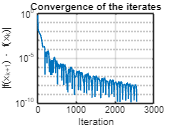

% Defining gradient function for least squares
grad = @(u) X_training' * (X_training * u - Y_training);

% Defining proximal operator for LASSO (soft-thresholding)
prox = @(u, lambda) sign(u) .* max(abs(u) - lambda, 0);  

% Initializing linear coefficients beta
beta0 = zeros(size(X_training,2), 1);

% Defining the regularization parameter and step size
lambda=0.05;
gamma= 1/norm(X_training' * X_training, 2);

% Model function describing the LASSO problem
model_f = @(u) 0.5 * norm(X_training * u - Y_training, 2)^2 + lambda * norm(u, 1);

% Calling FISTA function to solve the problem with
  %beta0=(0,...,0)
  %gamma=1/L where L=||X^tX||_2
  %lambda=0.05
  %tol=1e-6
beta = fista(beta0, gamma, lambda, 1e-6, grad, prox, model_f);


%Clearing variables for optimization
clear grad; clear prox; clear model_f; clear beta0;

The plot shows the convergence of FISTA for solving the LASSO problem with $\lambda=0.05$, with a rapid initial decrease followed by oscillations as it approaches numerical precision. This highlights the sublinear convergence $O(\frac{1}{k^2})$.

The best convergence is achieved with a step size $\gamma=\frac{1}{L}$, requiring 2553 iterations, compared to at least 3611 iterations with other step sizes like $\gamma=\frac{1}{2L}$. Using $\lambda=0.05$ the $\beta$ vector presents 2 null components. Increasing the regularization parameter to 0.5 the required iterations are reduced (1815 with $\gamma=\frac{1}{2L}$ and 1282 with $\gamma=\frac{1}{L}$) but leads to more null components (6), indicating stronger regularization. This results in simpler models that reduce overfitting but may overlook less dominant features, limiting the ability to capture patterns in solar flare data.

## STEP II: Optimal Threshold Computing

As described in the mathematical background, we determine the threshold that maximizes the TSS metric to evaluate prediction quality. 

Given the unbalanced data (85 no-flare, 15 flare), we notice TSS is particularly useful. 

% Generate predictions
p = X_training * beta;
y_true=Y_training;

% Defining a grid of thresholds
thresholds = linspace(min(p), max(p), 100);
   
% Defining the binary predicted labels matrix 100x100
% The rows describes the observations in y_true
% The columns describes the thresholds tested 
% Each row presents the predicted value of the observation for each threshold
y_pred = p >= thresholds; 

% Computing true and falses positive/negatives vectors
% Element-wise product of y_pred matrix and y_true vector is a matrix
% Summing the elements in each column we get a row vector 
% whose entrances are the number of positives and negatives for each threshold
TP = sum(y_pred.*(y_true), 1); 
TN = sum((1-y_pred).*(1-y_true), 1); 
FP = sum(y_pred.*(1-y_true), 1); 
FN = sum((1-y_pred).*(y_true), 1); 

% Calculating TSS and Accuracy values vector
% Each entrance correspond to the TSS/Accuracy value obtained for each threshold
tss_values = TP ./ (TP + FN) + TN ./ (TN + FP) - 1;
acc_values = (TP+TN) ./ (TP+TN+FP+FN);

% Finding the maximum value of TSS and its index
[max_tss, idx] = max(tss_values);

% Finding the optimal threshold the maximizes the TSS
optimal_threshold = thresholds(idx);

% Calculating the accuracy at the optimal threshold
optimal_accuracy = acc_values(idx);

% Printing the optimal threshold and its corresponding TSS and accuracy
fprintf('Optimal threshold: %.4f \n TSS: %.4f \n Accuracy: %.4f \n', optimal_threshold, max_tss, optimal_accuracy);

Optimal threshold: 0.1415 
 TSS: 0.7294 
 Accuracy: 0.9100 



% Clearing unused variables 
clear TP; clear TN; clear FP; clear FN; 

The TSS performance shows a peak at a threshold of 0.1415, with a maximum score of 0.7294. 

As illustrated by the plots in the code cell below, beyond this threshold point, the TSS score gradually declines as the threshold is increased.

While the accuracy is not maximized at the optimal TSS threshold of 0.1415, the 91% value still suggest a robust predictive model.

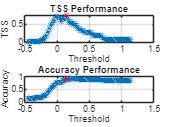

%-------------------------------------------PLOTTING----------------------------------------------------------
   
% Plotting TSS and Accuracy performances by varying the threshold,
% higlighting in red the optimal threshold value

figure();
% TSS plot
subplot(2, 1, 1); 
plot(thresholds, tss_values, '*');
hold on;
plot(optimal_threshold, max_tss, 'r*');
title('TSS Performance');
xlabel('Threshold'); ylabel('TSS'); grid on;
% Accuracy plot
subplot(2, 1, 2);
plot(thresholds, acc_values, '*');
hold on;
plot(optimal_threshold, optimal_accuracy, 'r*');
title('Accuracy Performance');
xlabel('Threshold'); ylabel('Accuracy'); grid on;

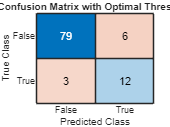


% Plotting Confusion Matrix obtained using the optimal threshold 
figure();
confusionchart(categorical(y_true, [0 1], ["False", "True"]), categorical(y_pred(:,idx), [0 1], ["False", "True"]));
title('Confusion Matrix with Optimal Threshold');


%Clearing unused variables
clear thresholds; clear acc_values; clear tss_values; clear idx; clear y_true; clear p; clear y_pred; 

The confusion matrix at the optimal threshold also shows an acceptable number of false positives and negatives. Notably, the number of false positives (6) is higher than false negatives (3), which is preferable as it’s better to manually verify a predicted flare than to miss a solar flare event.

## STEP III: Generalization

We now apply the model to the test set, corresponding to the solar event data from April 13, 2013. 

We classify whether a solar flare is likely to occur based on the test set’s features and on the optimal threshold determined in the previous section, providing an evaluation of the model's generalization to new, unseen data.

% Predicting the outcome classifying using the optimal threshold and
% displaying the result
if (X_test * beta >= optimal_threshold) == 1
    fprintf('Prediction: A solar flare is likely to occur!\n');
else
    fprintf('Prediction: No solar flare is likely to occur!\n');
end

Prediction: A solar flare is likely to occur!


The outcome is correct! 

On April 13, 2013, the Sun produced its strongest solar flare of the year, an M6.5 class flare, accompanied by a coronal mass ejection (CME) directed toward Earth. This event, captured in a false-color composite image from the Solar Dynamics Observatory reported below, originated from active region AR 11719 near the center of the solar disk. As solar maximum approaches, other sunspot groups are also visible, indicating regions of intense magnetic activity. 

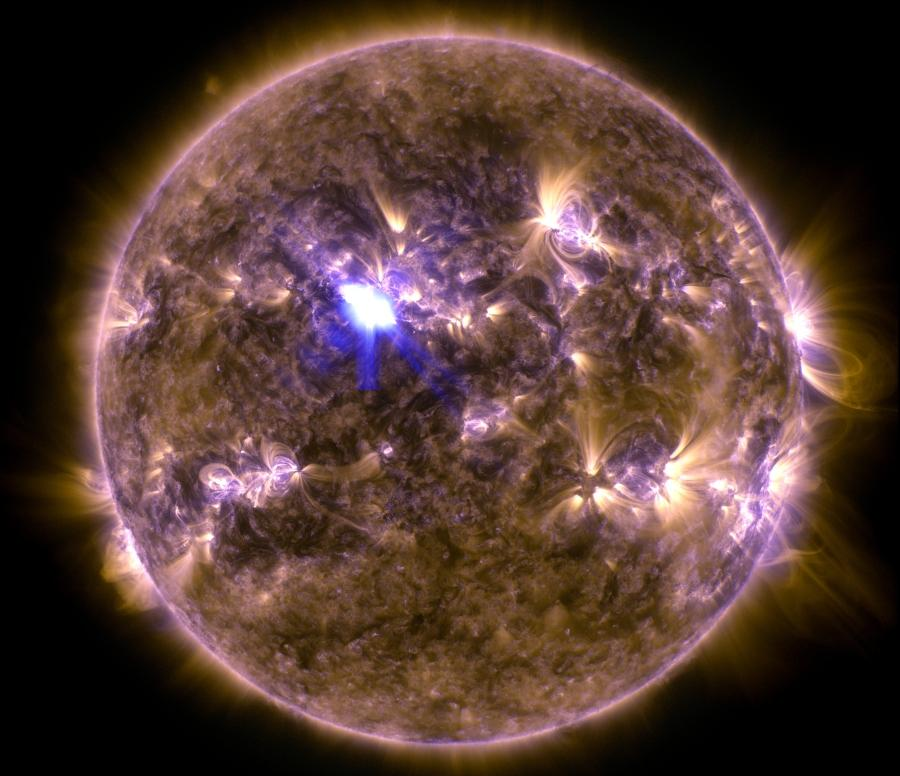

## FISTA Function

function [beta] = fista(beta0, gamma, lambda, tol, grad, prox, model_f)
    
    % INPUTS
    % beta0: initial guess for the coefficients vector
    % gamma: step size for gradient descent
    % lambda: regularization parameter
    % tol: tolerance for stopping criterion
    % grad: function handle for the gradient of the fidelity term function
    % prox: function handle for the proximity operator
    % model_f: function handle describing the model problem to solve
    
    % OUTPUT
    % beta: estimated coefficients vector after convergence
    
    %------------------------------------------INPUT CHECKS------------------------------------------------------
    
    % Beta dimensional check
    if ~isvector(beta0) || size(beta0, 2) ~= 1
        error('Beta (first input) must be a column vector.');
    end
    
    % Gamma dimensional check
    if gamma <= 0
        error('Step size (second input) must be positive.');
    end
    
    % Lambda dimensional check
    if lambda < 0
        error('Regularization parameter (third input) must be non-negative.');
    end
    
    % Tol dimensional check
    if tol <= 0
        error('Tolerance (fourth input) must be positive.');
    end
    
    % Grad dimensional check
    if ~isa(grad, 'function_handle')
        error('Grad function (fifth input) must be a valid function handle.');
    end
    
    % Prox dimensional check
    if ~isa(prox, 'function_handle')
        error('Prox function (sixth input) must be a valid function handle.');
    end

    % model_f dimensional check
    if ~isa(model_f, 'function_handle')
        error('Model function (seventh input) must be a valid function handle.');
    end
    
    %------------------------------------------INITIALIZATION------------------------------------------------------
    
    % Initializing momentum parameters for acceleration 
    alpha = beta0; 
    t = 1; 
    
    % Initializing iteration counter and maximum iteration number
    iteration = 0; 
    max_iter = 5000;
    
    % Array which will contain the difference of the iterates f(x_{k+1})-f(x_k)
    % Pre-allocating for speed
    iterates_diff = [];
    
    % Evaluation of model function with the beta0  
    prev_value = model_f(beta0);
    
    %----------------------------------------------ALGORITHM-------------------------------------------------------
    
    % Computing the algorithm until the maximum iteration is reached
    for k = 1:max_iter
    
        % Computing beta coefficients
        beta_new = prox(alpha - gamma * grad(alpha), gamma * lambda);  
    
        % Updating momentum parameters 
        t_new = (1 + sqrt(1 + 4 * t^2)) / 2;
        alpha_new = beta_new + ((t - 1) / t_new) * (beta_new - beta0);
        
        % Computing the current value of model function evaluated in beta_k
        curr_value = model_f(beta_new);
        
        % Computing difference of the iterates f(x_{k+1})-f(x_k)
        iterates_diff = [iterates_diff; abs(curr_value - prev_value)];
        
        % Updating the evaluation of model function
        prev_value = curr_value;
        
        % Checking stopping criterion
        if norm(beta_new - beta0, 2) < tol * norm(beta_new, 2)
            beta = beta_new;
            break;
        end
        
        % Updating beta, alpha, t, and iteration count for next iteration
        beta0 = beta_new; 
        alpha = alpha_new; 
        t = t_new;
        iteration = iteration + 1;
    end
    
    %----------------------------------PRINTING ITERATIONS AND BETA NULL COMPONENTS--------------------------------
    
    % Iterations required to convergence
    if k == max_iter
        fprintf('Convergence not reached in %d iterations.\n', max_iter);
    else
        fprintf('Convergence reached in %d iterations.\n', iteration);
    end
    
    % Number of null components of beta
    num_null_components = length(beta_new) - nnz(beta_new); 
    fprintf('Beta vector presents %d null components.\n', num_null_components);

    %-------------------------------------------PLOTTING----------------------------------------------------------
    
    % Iterates plot 
    figure();
    semilogy(iterates_diff, '-');
    title('Convergence of the iterates');
    xlabel('Iteration');
    ylabel('|f(x_{k+1}) - f(x_k)|');
    grid on;
end